unzip("DigitsData.zip")
imds = imageDatastore("DigitsData", ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");
numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,"randomized");
classNames = categories(imdsTrain.Labels)

classNames = 10×1 cell array
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


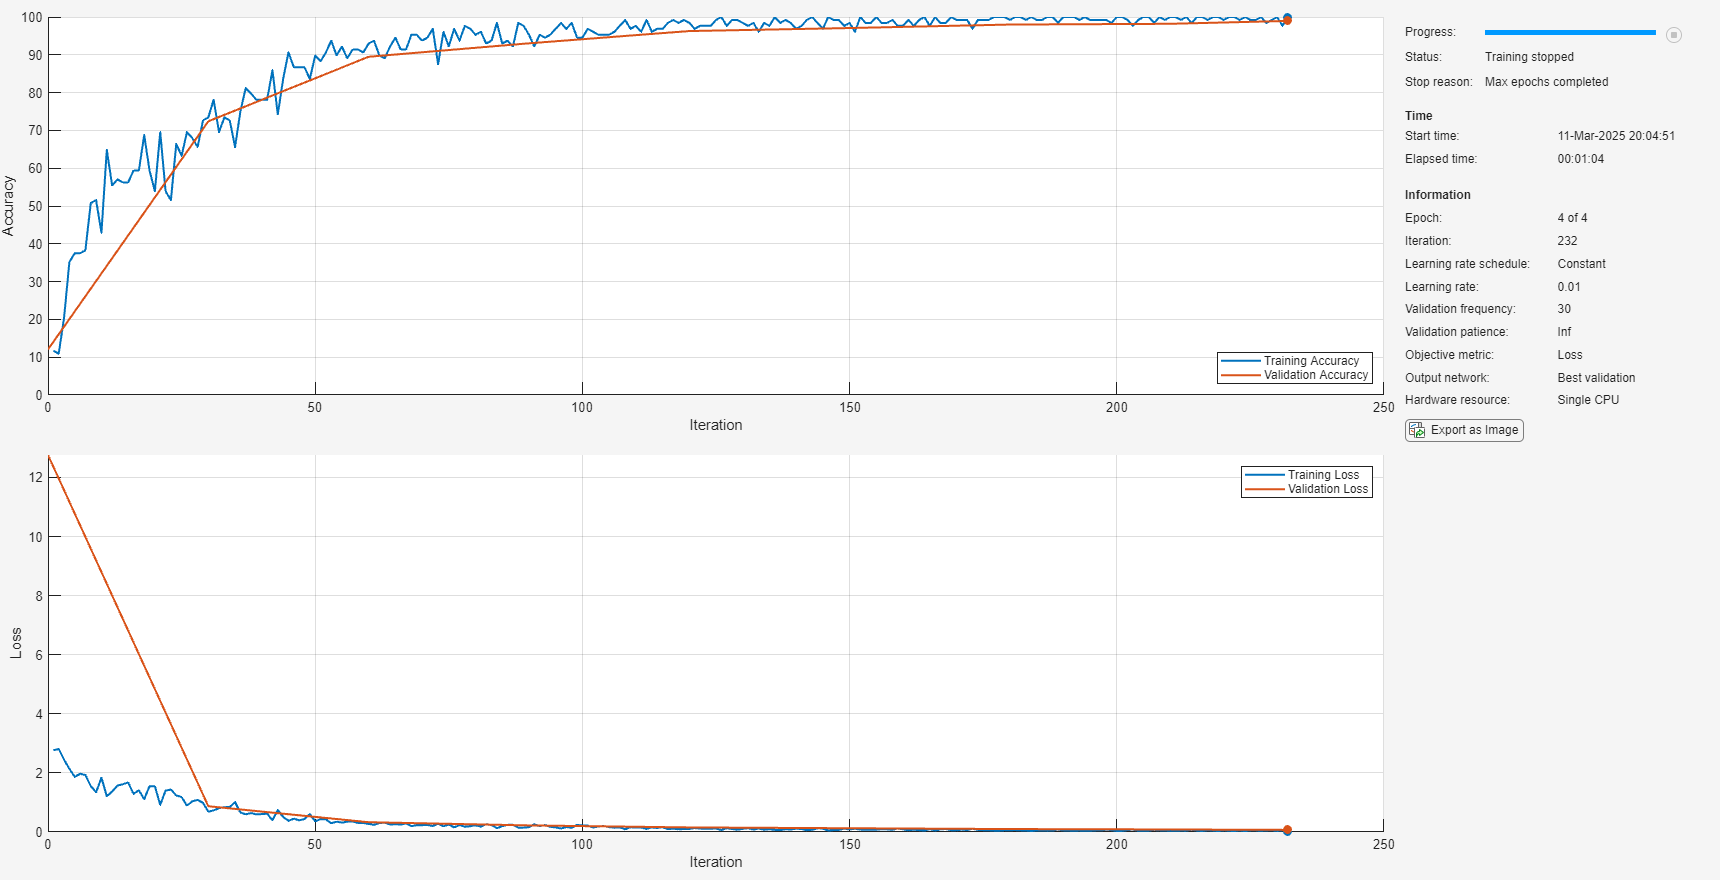

inputSize = [28 28 1];
numClasses = 10;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];
options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);
net = trainnet(imdsTrain,layers,"crossentropy",options);

scores = minibatchpredict(net,imdsValidation);
YValidation = scores2label(scores,classNames);
TValidation = imdsValidation.Labels;
accuracy = mean(YValidation == TValidation)

accuracy = 0.9896